# Reconstruction vSLAM Doc 

## Created by: Alejandro Boadella (EETAC-UPC)

*References: MATLAB sources and examples.*

In this code, fast movement of the camera and lack of landmarks can make the code loss the track of the hardware, leading a non or a partial reconstruction of the scenario.

clear all
format long

Connect raspberry pi via ip address, put user and password to do SSH connection.

Enable camera, load camera calibration matrix and allocate folders.

mypi = raspi('192.168.2.100','AlexTFG','TFG');
camera = cameraboard(mypi,'Resolution','1920x1080','Quality',100,'FrameRate',30);
load calibracion4.mat

## Option 1:

Loop: Take a snapshot, divide the image into 2 (2 cameras), rectify the images and save them into a folder.

ImageFolder_left ='C:\Users\alexb\Desktop\Left_video';
ImageFolder_right ='C:\Users\alexb\Desktop\Right_video';
k=1;

while true

    img = snapshot(camera);
    img_left =img(:, 1:end/2,:);
    img_right = img(:, end/2+1:end,:);
    [frameLeftRect, frameRightRect, reprojectionMatrix] = rectifyStereoImages(img_left, img_right, ...
        stereoParams,"linear");
    file_name_1 = sprintf('Image%d.jpg',k);
    file_name_2 = sprintf('Image%d.jpg',k);
    imgName_1 = fullfile(ImageFolder_left,file_name_1);
    imwrite(frameLeftRect,imgName_1,'Quality',100);
    imgName_2 = fullfile(ImageFolder_right,file_name_2) ;
    imwrite(frameRightRect,imgName_2,'Quality',100);
    k=k+1;
    
end

## Option 2: (best option)

Instead of taking pictures, record with the raspberry pi video. Another method to record a video is using raspberry pi commands. Furthermore resolutions can be changed using different command structure.

For example:  raspivid -t seconds*1000 -o video.h264

MATLAB command to send: system(mypi,'raspivid -t seconds*1000 -o video.h264');

seconds=40;
record(camera,'myvideo.h264',seconds);

Obtain the h264 file. 

getFile(mypi,'myvideo.h264','C:\Users\alexb\Dropbox\ALEX\UPC\TFG');

Delete the file inside the raspberry pi.

deleteFile(mypi,'myvideo.h264');

MATLAB is unable to read directly an h264 video format, so mp4 conversion shall be done. This is done with FFMPEG. (newest version might be playable in MATLAB) (It only works for small video less than 10 seconds. The best option is to test it. Use other programmes conversions if the length of the video is too high!!!)

Specify the h264 path and video file, specify the path and file of the desired mp4 video.

Select the frame rate , specify the folder of the ffmpeg program (this program is free, just search and download from internet). Then a windows command will be executed and the status will tell if the conversion was successful.

h264FilePath = 'C:\Users\alexb\Dropbox\ALEX\UPC\TFG\myvideo.h264'; 
mp4FilePath = 'C:\Users\alexb\Dropbox\ALEX\UPC\TFG\file.mp4'; 
frame_rate='24';
ffmpegDir = 'C:\Users\alexb\Desktop\ffmpeg-master-latest-win64-gpl\ffmpeg-master-latest-win64-gpl';
ff = fullfile(ffmpegDir, 'bin', 'ffmpeg.exe');
ffmpegCommand = sprintf('%s  -framerate %s -i %s -c copy %s', ff, frame_rate, h264FilePath, mp4FilePath)

ffmpegCommand = 'C:\Users\alexb\Desktop\ffmpeg-master-latest-win64-gpl\ffmpeg-master-latest-win64-gpl\bin\ffmpeg.exe -ss 00:00:00 -i C:\Users\alexb\Dropbox\ALEX\UPC\TFG\myvideo.h264 -to 00:01:00 -vcodec copy C:\Users\alexb\Dropbox\ALEX\UPC\TFG\file.mp4'

status = system(ffmpegCommand); 

ffmpeg version N-114525-gba7980d9c0-20240330 Copyright (c) 2000-2024 the FFmpeg developers 
  built with gcc 13.2.0 (crosstool-NG 1.26.0.65_ecc5e41) 
  configuration: --prefix=/ffbuild/prefix --pkg-config-flags=--static --pkg-config=pkg-config --cross-prefix=x86_64-w64-mingw32- --arch=x86_64 --target-os=mingw32 --enable-gpl --enable-version3 --disable-debug --disable-w32threads --enable-pthreads --enable-iconv --enable-libxml2 --enable-zlib --enable-libfreetype --enable-libfribidi --enable-gmp --enable-fontconfig --enable-libharfbuzz --enable-libvorbis --enable-opencl --disable-libpulse --enable-libvmaf --disable-libxcb --disable-xlib --enable-amf --enable-libaom --enable-libaribb24 --enable-avisynth --enable-chromaprint --enable-libdav1d --enable-libdavs2 --enable-libdvdread --enable-libdvdnav --disable-libfdk-aac --enable-ffnvcodec --enable-cuda-llvm --enable-frei0r --enable-libgme --enable-libkvazaar --enable-libaribcaption --enable-libass --enable-libbluray --enable-libjxl --enable

if status == 0 
    disp('Conversion completed successfully.'); 
else 
    disp('Conversion failed.'); 
end 

Conversion completed successfully.


Create 2 folder for the 2 cameras. The code reads the mp4 video (video path) and takes a picture, after that, the picture is rectified and saved in those folders.

ImageFolder_left ='C:\Users\Alex\Desktop\Vid2\Left';
ImageFolder_right ='C:\Users\Alex\Desktop\Vid2\Right';

vid = VideoReader('C:\Users\Alex\Dropbox\ALEX\UPC\TFG\Videos\myvideo_2.mp4')

vid =   VideoReader with properties:

   General Properties:
            Name: 'myvideo_2.mp4'
            Path: 'C:\Users\Alex\Dropbox\ALEX\UPC\TFG\Videos'
        Duration: 47.799999999999997
     CurrentTime: 0.160000000000000
       NumFrames: <Calculating...> learn more

   Video Properties:
           Width: 1920
          Height: 1080
       FrameRate: 25
    BitsPerPixel: 24
     VideoFormat: 'RGB24'



for k = 1:vid.NumberOfFrames
    img=read(vid, k);
    img_left =img(:, 1:end/2,:);
    img_right = img(:, end/2+1:end,:);
    [frameLeftRect, frameRightRect, reprojectionMatrix] = rectifyStereoImages(img_left, img_right, ...
        stereoParams,"linear");
    file_name_1 = sprintf('Image%d.jpg',k);
    file_name_2 = sprintf('Image%d.jpg',k);
    imgName_1 = fullfile(ImageFolder_left,file_name_1);
    imwrite(frameLeftRect,imgName_1,'Quality',100);
    imgName_2 = fullfile(ImageFolder_right,file_name_2) ;
    imwrite(frameRightRect,imgName_2,'Quality',100);
    k=k+1;
end


## Preparing datastores:

Load the re-projection matrix, that can be obtained with the calibration parameters.

Obtain the path where video images are or individual taken photos are (fullfile function in case of several paths is used). Create an image datastore to manage all the images with less computational work. Finally a sorting algorithm in case of indexing image error in the datastore. In order to sort these files, Natsortfiles Add-on from MATLAB has been used. The indexing error is a common error though sometimes doesn't appear, depending how the images are named.

load reprojectionMatrix_2.mat

imgFoldersLeft = fullfile('C:\Users\Alex\Desktop\Vid\Left');
imgFoldersRight = fullfile('C:\Users\Alex\Desktop\Vid\Right');
imdsLeft = imageDatastore(imgFoldersLeft);
imdsRight = imageDatastore(imgFoldersRight);
imdsLeft.Files = natsortfiles(imdsLeft.Files);
imdsRight.Files = natsortfiles(imdsRight.Files);


## Test code (no importance):

This code is only for testing the images disparity of the images of the datastore.

It hasn't got an important role in the reconstruction. Disparity parameter can be changed, specially in the threshold aspect to view the patch size in the disparity map.

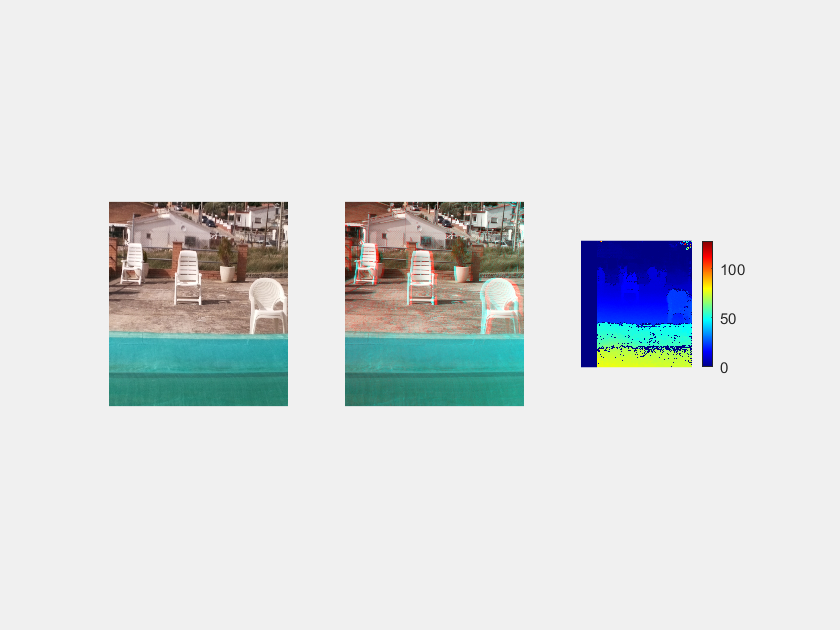

frameLeftRect = readimage(imdsLeft,28);
frameRightRect = readimage(imdsRight,28);
frameLeftGray  = im2gray(frameLeftRect);
frameRightGray = im2gray(frameRightRect);

f=figure(1);
set(f, 'Visible', 'on');
combinationimages= stereoAnaglyph(frameLeftRect, frameRightRect);
disparityMap = disparitySGM(frameLeftGray,frameRightGray,DisparityRange=[0 128],UniquenessThreshold=7);
hold on;
subplot(1,3,1);
imshow(frameLeftRect);
subplot(1,3,2);
imshow(combinationimages);
subplot(1,3,3);
imshow(disparityMap,[0 128]);
colormap jet
colorbar
hold off;

## Starting vSLAM, Detecting features/landmarks and tracking:

Selecting in what frame we want to start ("start"). Then analyzing how big the images are.

Creating an slam object (14 levels of pyramidal detection, recall ORB), other configuration not mention, very sensitive in parameters changing. 

This code detects a useful key frame to detect the position of the hardware and its surrounding, then passes this frame to the slam object, which calculates and determines the position/track and all the features. Some code is deactivated, it can be activated for curiosity. But no important role is occupied.

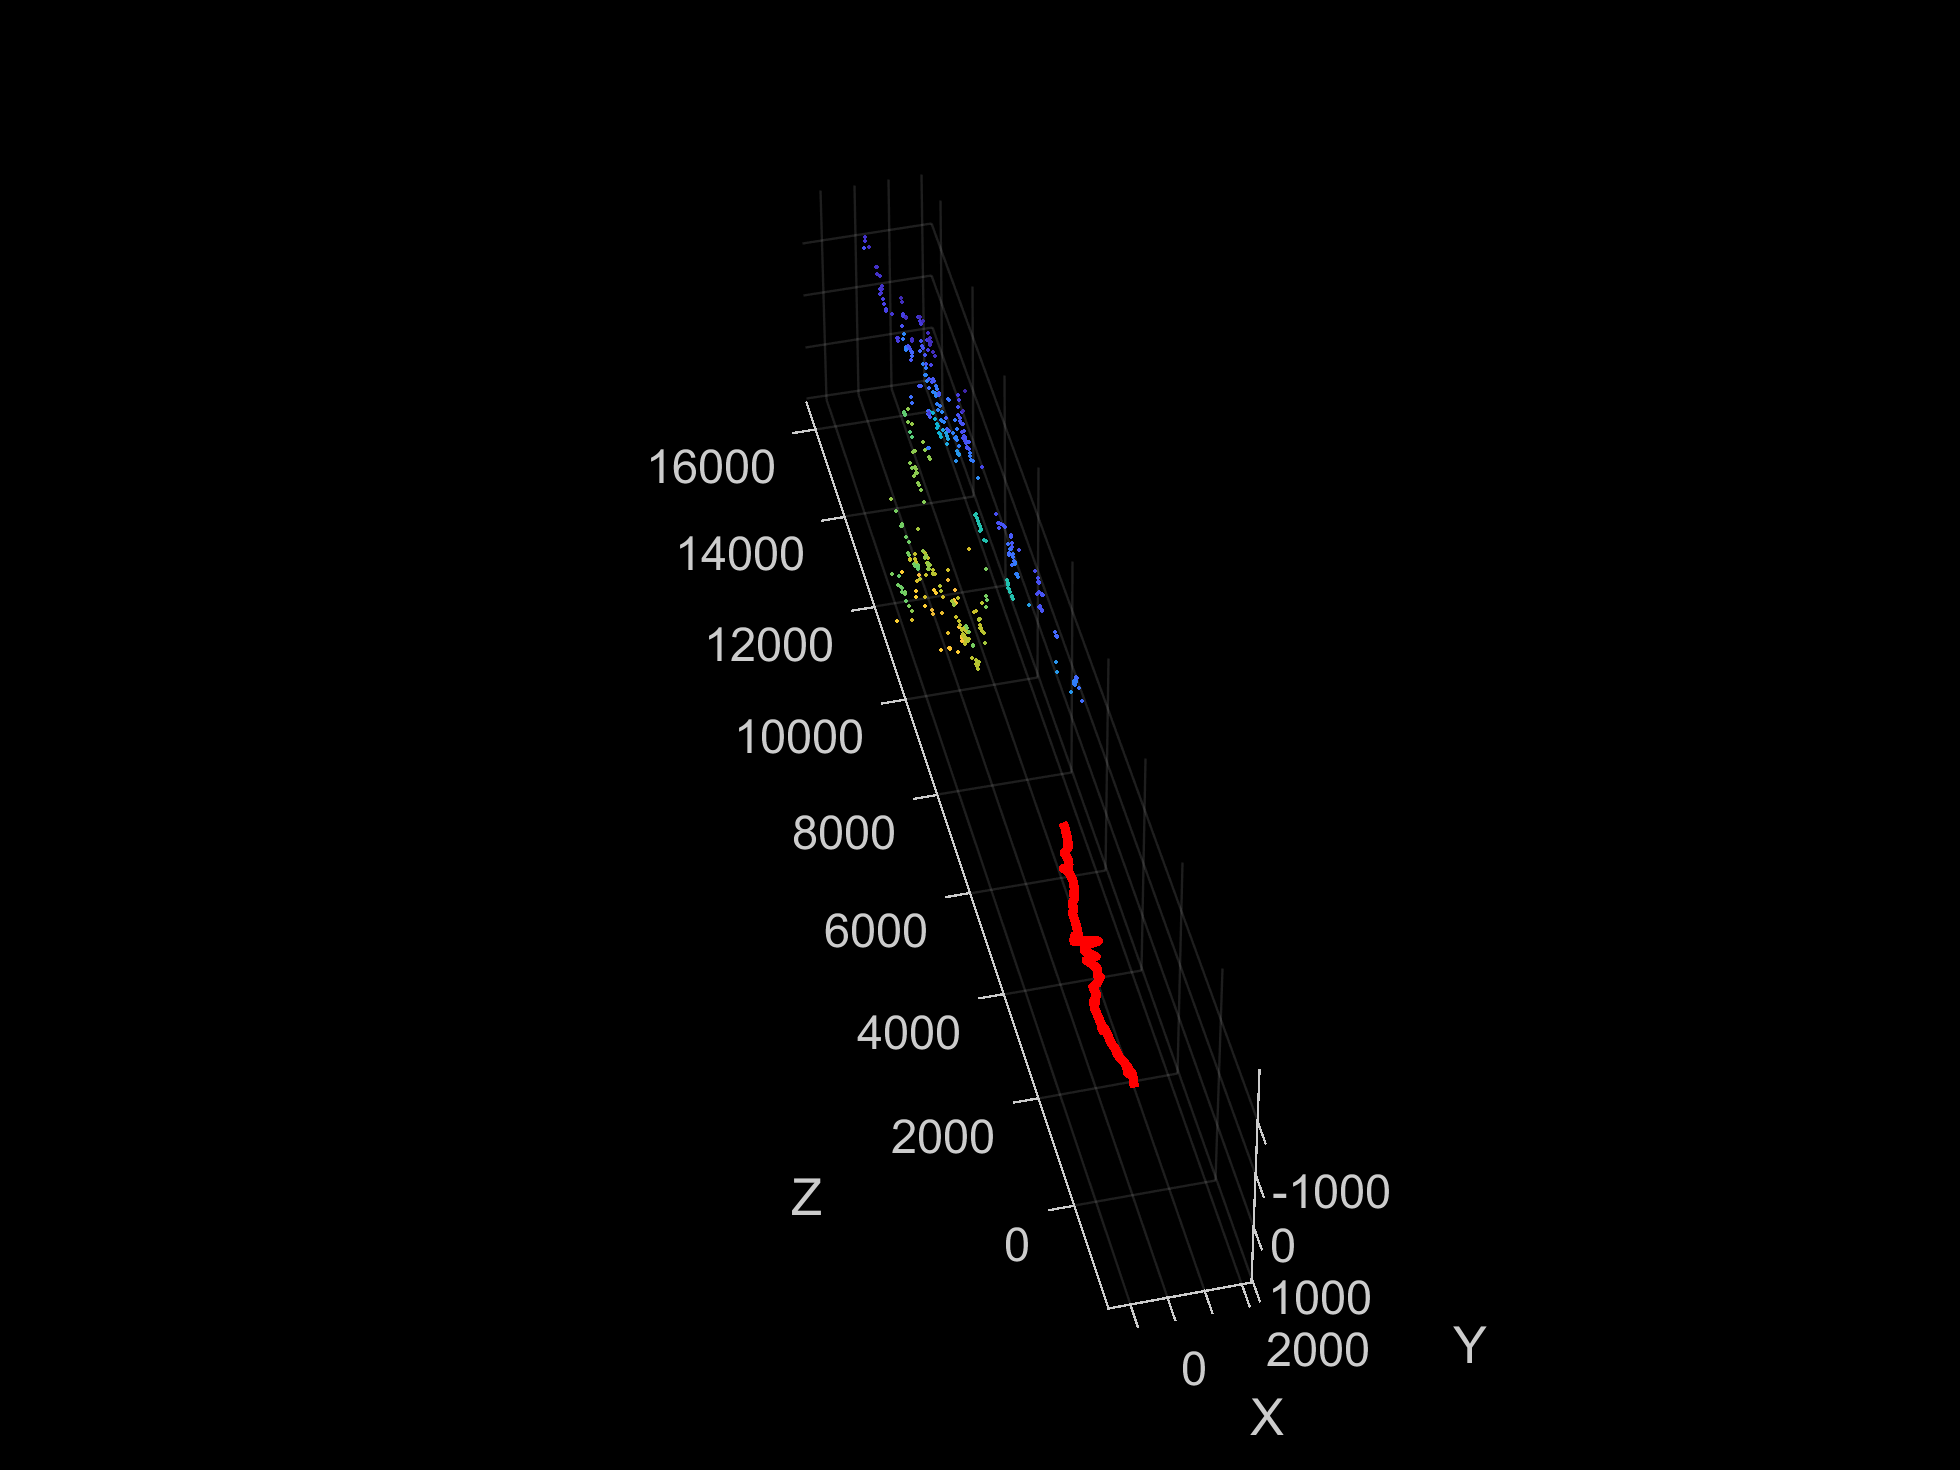

start=500;
imageSize = size(readimage(imdsLeft,1),[1,2]);% in pixels [mrows, ncols]

vslam = stereovslam(reprojectionMatrix, imageSize, SkipMaxFrames=5, NumLevels=14, UniquenessThreshold=50);

for i = start:numel(imdsLeft.Files)

    frameLeftRect = readimage(imdsLeft,i);
    frameRightRect = readimage(imdsRight,i);
    % Pass each stereo image frame to the vSLAM algorithm.
    addFrame(vslam,frameLeftRect,frameRightRect);

    if hasNewKeyFrame(vslam)
        % Display 3D map points and camera trajectory
        ax = plot(vslam);
        
    end
    %status = checkStatus(vslam)
end


% while ~isDone(vslam)
%     if hasNewKeyFrame(vslam)
%         ax = plot(vslam);
%     end
% end
figure(1)
% Retrieve camera poses and key frame 
[camPoses,keyFrameIDs] = poses(vslam);
estimatedTrajectory = vertcat(camPoses.Translation);

numKeyFrames = numel(keyFrameIDs);
ptClouds = repmat(pointCloud(zeros(1,3)),numKeyFrames,1);

## Reconstruction:

Predefining a disparity range of the pixels.

Basically this code is the creation with the key frames of disparity maps using the images. Then from this disparity maps with the re-projection matrix create a point cloud (a set of pixels point in the space xyz. Apply color from the left image to this cloud point, and finally a stitching the different cloud points of the key frames to generate a main cloud point.

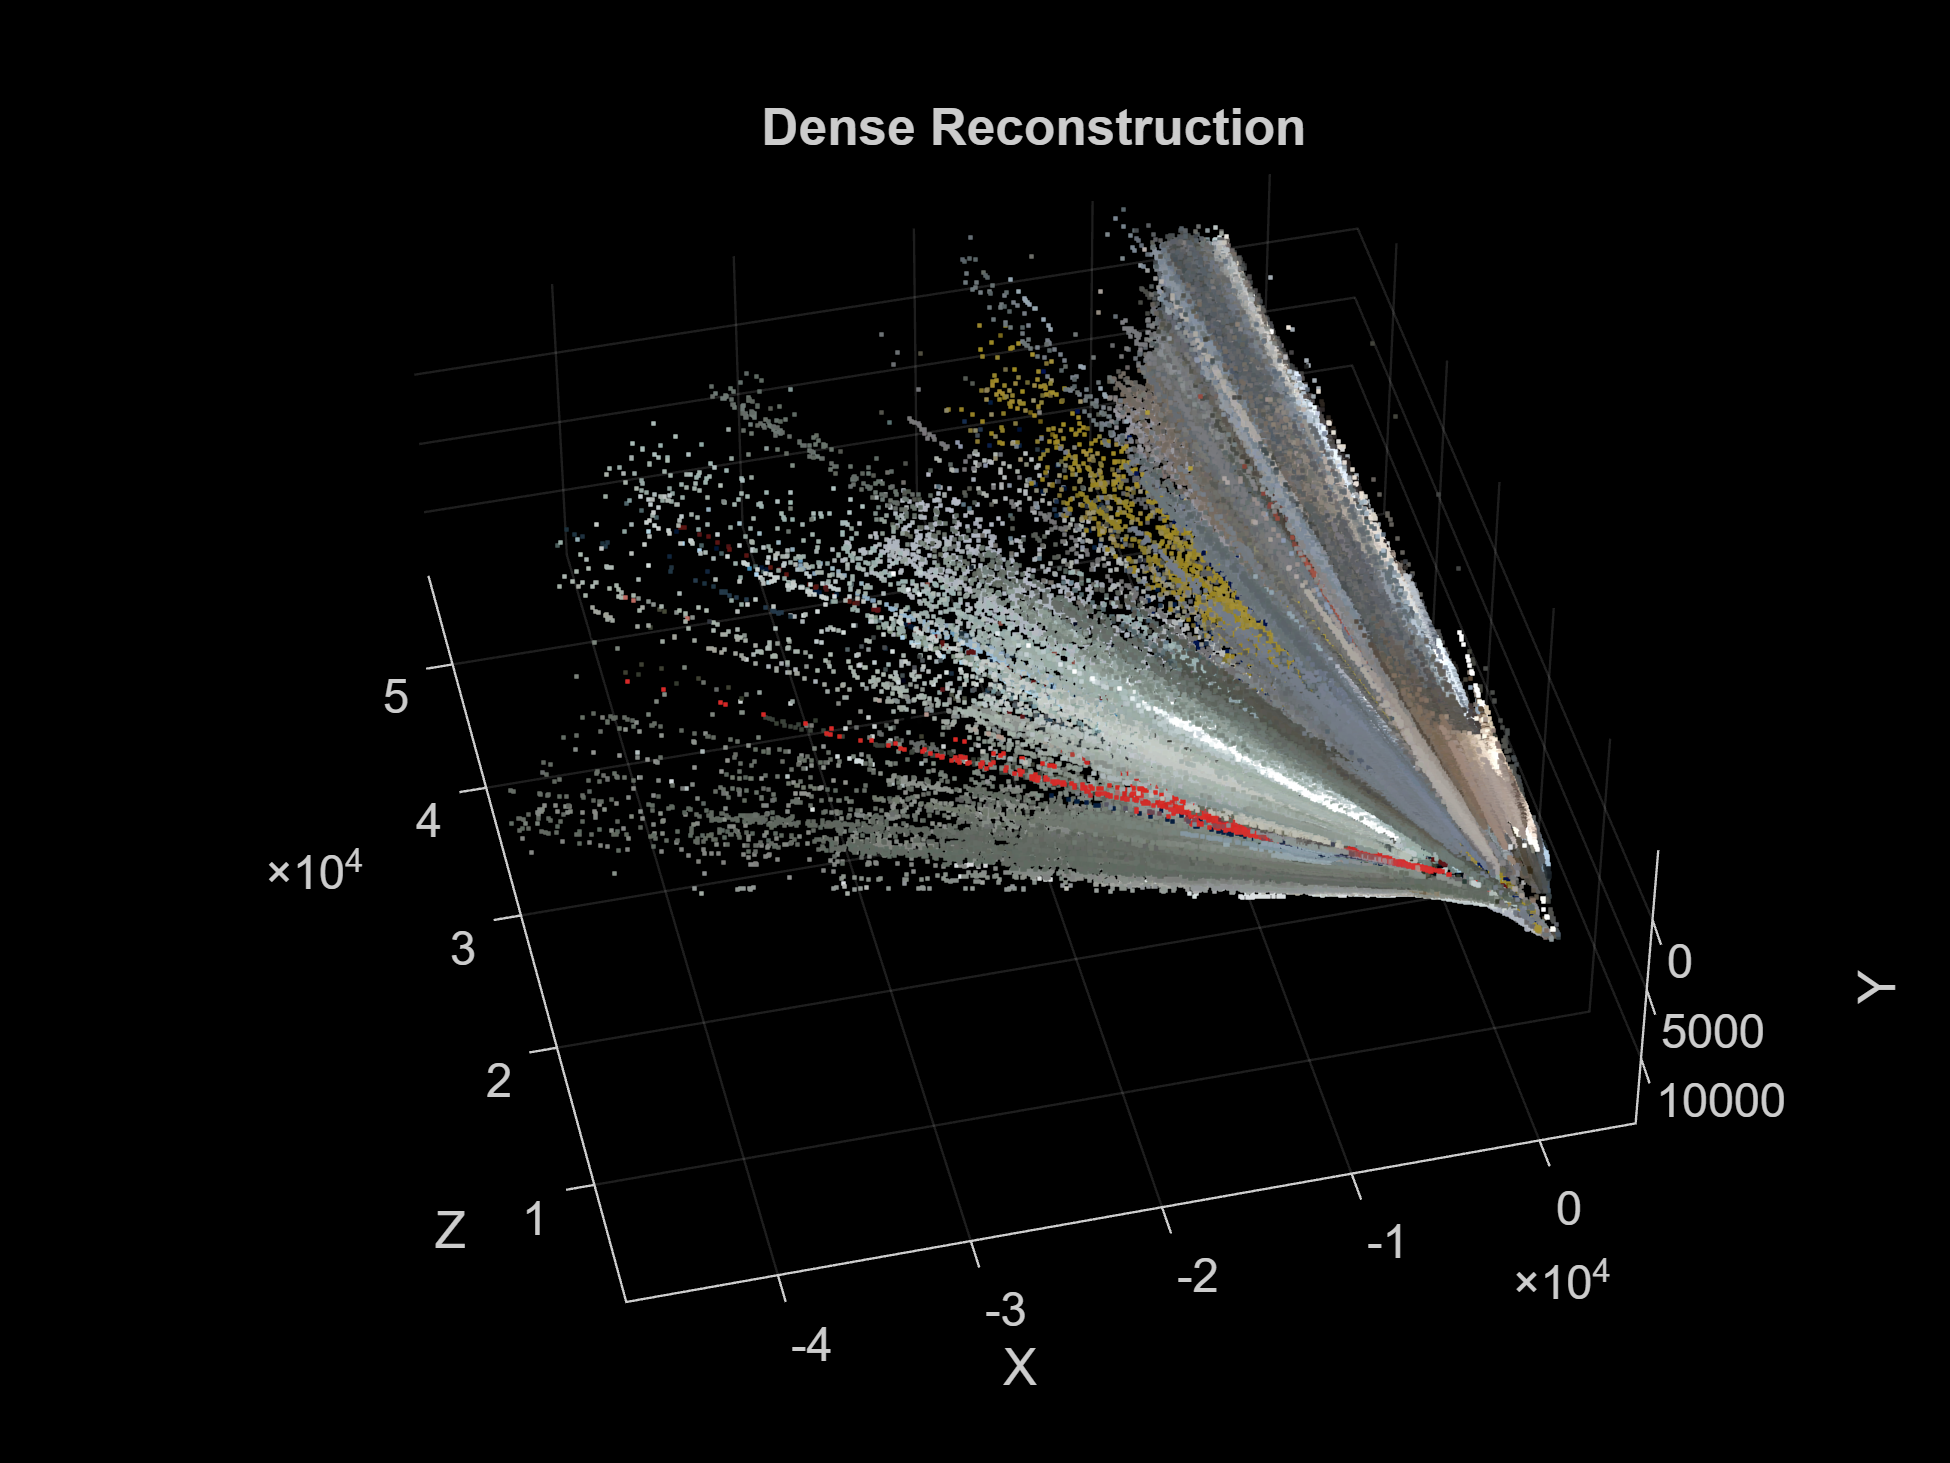

disparityRange = [0 128]; 
i=1;
for i = 1:numKeyFrames

    frameLeftRect = readimage(imdsLeft,double(keyFrameIDs(i)+start-1));
    frameRightRect = readimage(imdsRight,double(keyFrameIDs(i)+start-1));
    imageSize = size(frameLeftRect,[1,2]);% in pixels [mrows, ncols]

    frameLeftGray = im2gray(frameLeftRect);
    frameRightGray = im2gray(frameRightRect);
    % Reconstruct scene from disparity
    disparityMap = disparitySGM(frameLeftGray,frameRightGray,DisparityRange=disparityRange, UniquenessThreshold=7);
    xyzPoints = reconstructScene(disparityMap,reprojectionMatrix);

    xyzPoints(1:100,:,:) = NaN;

    xyzPoints  = reshape(xyzPoints, [imageSize(1)*imageSize(2), 3]);

    % Get color from the color image
    colors = reshape(frameLeftRect, [imageSize(1)*imageSize(2), 3]);

    % Remove world points that are behind 
    % Distant points can be annoying
    % Delete them using and varying the following example in validIndex: 
    %   [ & xyzPoints(:,3) < 100/reprojectionMatrix(4,3)];
    % If the user want to remove some the pixels modify validIndex  
    validIndex = xyzPoints(:,3) > 0 & xyzPoints(:,3) < 700/reprojectionMatrix(4,3) ;  
    xyzPoints = xyzPoints(validIndex,:);
    colors = colors(validIndex,:);
    
    % Transform world points to the world coordinates
    xyzPoints  = transformPointsForward(camPoses(i),xyzPoints);
    ptClouds(i) = pointCloud(xyzPoints, Color=colors);

    % Downsample the point cloud
    ptClouds(i) = pcdownsample(ptClouds(i),random=0.5); 
end

% Concatenate the point clouds into a single
pointCloudsAll = pccat(ptClouds);

figure(2)
ax = pcshow(pointCloudsAll,VerticalAxis="y", VerticalAxisDir="down");
xlabel('X')
ylabel('Y')
zlabel('Z')
title('Dense Reconstruction')

This code is the visualization in first point of view and in 3D perspective of the recorded data.

Pretty useful indeed, to generate and visualize distance depth.

% Visualize the point cloud
viewer = pcviewer(pointCloudsAll,VerticalAxis="YDown");

% Navigate to the first camera pose
viewer.CameraUpVector = [0 -1 0];
for i = 1:numKeyFrames
    position = camPoses(i).Translation;
    target = [0 0 1 1]*camPoses(i).A';
    viewer.CameraPosition = position;
    viewer.CameraTarget = target(1:3);
    pause(0.1);
end
